Write a MATLAB code for amplitude modulation of DSB-FC

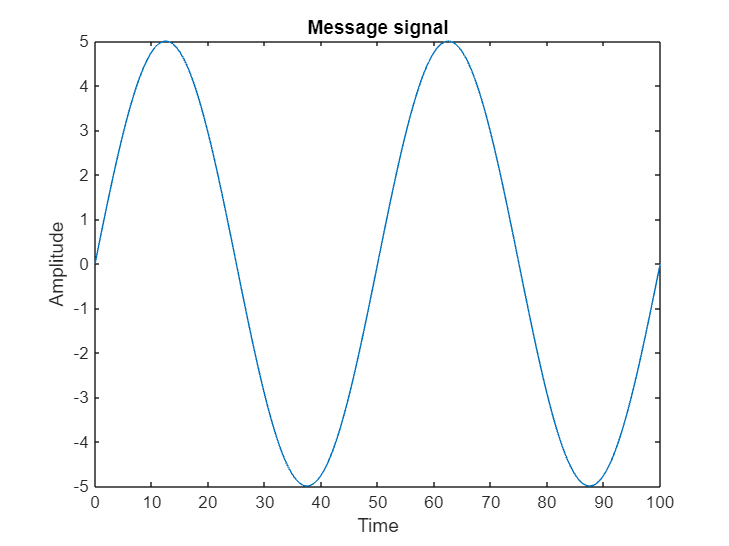

clc;
clear all;
% Generating the message signal
Am = input('Enter the amplitude of the message signal: ');
fm = input('Enter the frequency of the message signal: ');
t = linspace(0,100,5000);
x1 = Am * sin(2*pi*fm*t);
plot(t,x1);
xlabel('Time');
ylabel('Amplitude');
title('Message signal');

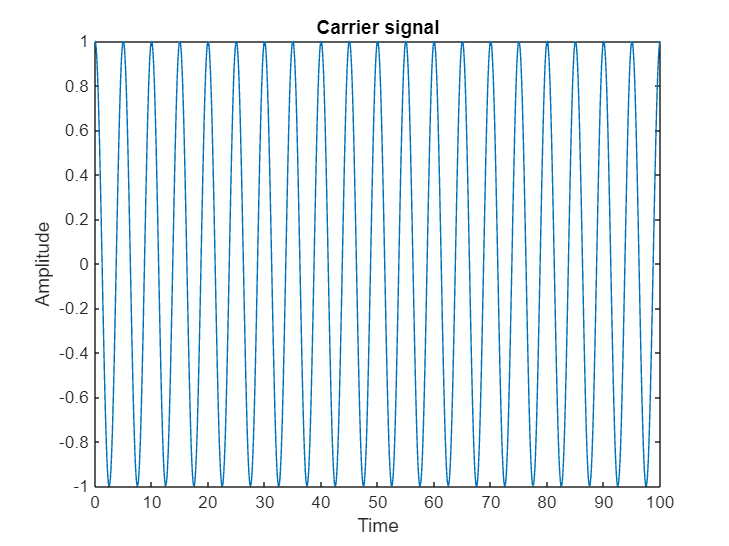

% Generating the carrier signal
fc = input('Enter the frequency of the carrier signal: ');
c1 = cos(2*pi*fc*t);
plot(t,c1);
xlabel('Time');
ylabel('Amplitude');
title('Carrier signal');

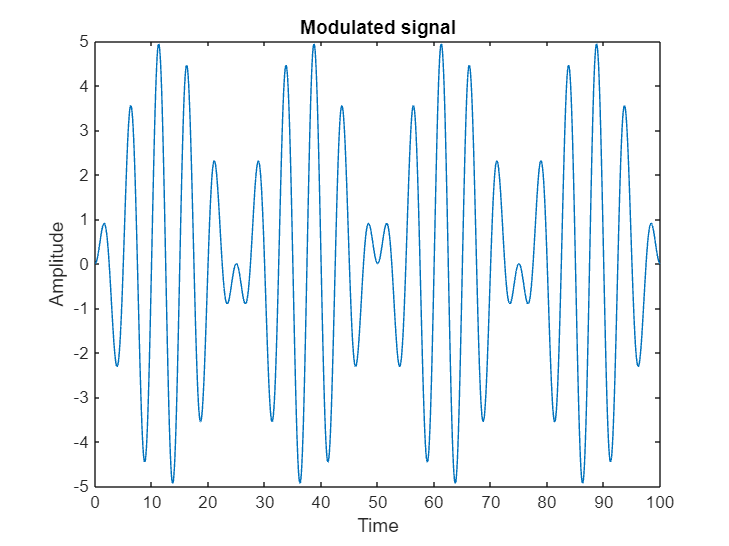

% Comparing freuency of message and carrier
if fc < fm
    disp("Please choose carrier frequency greater than message frequency");
end
% Generating the modulated signal
s1 = x1 .* sin(2*pi*fc*t);
plot(t,s1);
xlabel('Time');
ylabel('Amplitude');
title('Modulated signal');